oHovCLA = 'C:\Users\maran\MATLAB Drive\thesisFinal\results\oCRhovCLA.csv'

oHovCLA = 'C:\Users\maran\MATLAB Drive\thesisFinal\results\oCRhovCLA.csv'


M = csvread(oHovCLA)

M =          0    0.0460
    0.2000    0.0944
    0.4000    0.3170
    0.6000    0.7641
    0.8000    1.0060
    1.0000    0.9885
    1.2000    0.9573
    1.4000    0.9734
    1.6000    1.0018
    1.8000    1.0190



x = M(:,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000
    1.8000


y = M(:,2)

y =     0.0460
    0.0944
    0.3170
    0.7641
    1.0060
    0.9885
    0.9573
    0.9734
    1.0018
    1.0190


xx = x/5

xx =          0
    0.0400
    0.0800
    0.1200
    0.1600
    0.2000
    0.2400
    0.2800
    0.3200
    0.3600



S = stepinfo(M)

S = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


%ss = stepinfo(y,xx)

rise = S(2,1).RiseTime

rise = 2.6923

sTime = S(2,1).SettlingTime

sTime = 16.6030

sMin = S(2,1).SettlingMin

sMin = 0.9573

sMax = S(2,1).SettlingMax

sMax = 1.1029

oS = S(2,1).Overshoot

oS = 0.3914

peak = S(2,1).Peak

peak = 1.1029

peakTime = S(2,1).PeakTime

peakTime = 33


timeM = [rise; sTime; sMin; sMax; oS]

timeM =     2.6923
   16.6030
    0.9573
    1.1029
    0.3914


timM = timeM*5

timM =    13.4615
   83.0152
    4.7865
    5.5145
    1.9570



sourceRowNum = round(timM(1,:))         

sourceRowNum = 13

riseV = M(sourceRowNum,:)

riseV =     2.4000    1.0552



%sourceRowNum = round(timM(2,:))         
%sTimeV = M(sourceRowNum,:)

sourceRowNum = round(timM(3,:))         

sourceRowNum = 5

sMinV = M(sourceRowNum,:)

sMinV =     0.8000    1.0060



sourceRowNum = round(timM(4,:))         

sourceRowNum = 6

sMaxV = M(sourceRowNum,:)

sMaxV =     1.0000    0.9885



sourceRowNum = round(timM(5,:))         

sourceRowNum = 2

overshootV = M(sourceRowNum,:)

overshootV =     0.2000    0.0944




peakTime = peakTime/5

peakTime = 6.6000


stepData = [riseV; sMinV; peakTime, peak;]

stepData =     2.4000    1.0552
    0.8000    1.0060
    6.6000    1.1029


%t = table(stepData)

%sT = num2str(sTime,'%.1d')

hold on
plot(x,y)
plot(stepData(:,1),stepData(:,2),'+','MarkerSize',12)
xvvv = xline(rise,'--m',{'Settling Time'});
%xvv = xline(sTime, '--m', {'Settling Time'})

xv = xline(peakTime,'-.g',{'PeakTime'})

xv =   ConstantLine (PeakTime) with properties:

    InterceptAxis: 'x'
            Value: 6.6000
            Color: [0 1 0]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: {'PeakTime'}
      DisplayName: ''

  Show all properties


xv.LabelVerticalAlignment = 'middle';
%xvv.LabelVerticalAlignment = 'middle';
xvvv.LabelVerticalAlignment = 'middle';
yline(peak,'-.g',{'Peak'})

ans =   ConstantLine (Peak) with properties:

    InterceptAxis: 'y'
            Value: 1.1029
            Color: [0 1 0]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: {'Peak'}
      DisplayName: ''

  Show all properties


yline(sMinV(:,2),'-.c',{'Undershoot'})

ans =   ConstantLine (Undershoot) with properties:

    InterceptAxis: 'y'
            Value: 1.0060
            Color: [0 1 1]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: {'Undershoot'}
      DisplayName: ''

  Show all properties


xline(sMinV(:,1),'-.c')

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 0.8000
            Color: [0 1 1]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


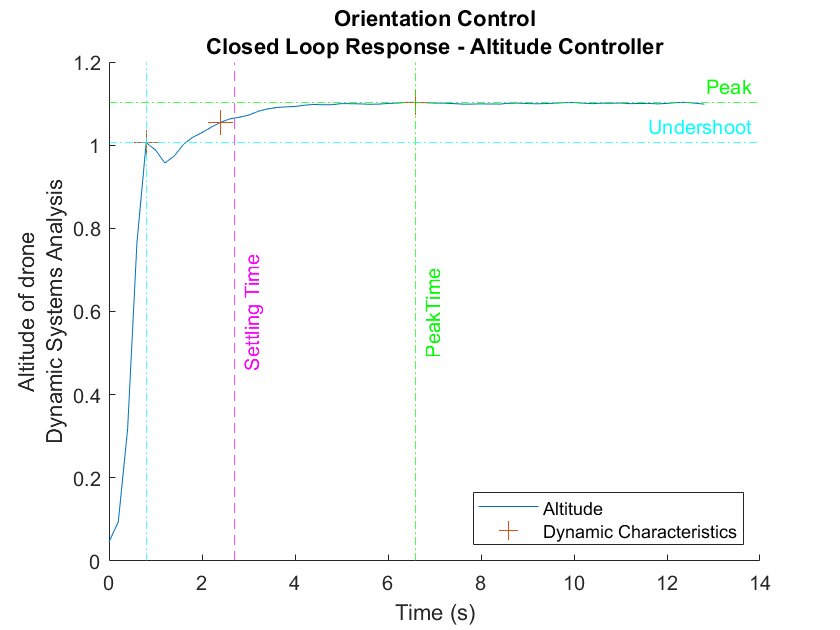


xlabel('Time (s)');
ylabel({'Altitude of drone';'Dynamic Systems Analysis'})
title({'Orientation Control';'Closed Loop Response - Altitude Controller'})
legend({'Altitude'; 'Dynamic Characteristics'},'Location','southeast')


% twocolmat = rand(100,2)
% idx = twocolmat(:,2) %>= 0.2
% idx*1000
% k = find(idx == 5752)
% %col2vals = twocolmat(idx,2)